clc;clear;close all;
f=@(x)tan(x).*tanh(x)+1;
df=@(x)tan(x).*sech(x).^2+tanh(x)+sec(x).^2;

x0=1;
max_iteration=100;
tol=1e-8;

for i=1:max_iteration
    xnew=x0-f(x0)./df(x0);
    if abs(xnew - x0) < tol
        break;
    end
    x0 = xnew;
end
fprintf('newton method root: %.8f found in %d iteration\n',xnew,i);

newton method root: -1.57079633 found in 14 iteration



x_zeros=fzero(f,1);
fprintf('fzero root: %.8f\n', x_zeros);

fzero root: 1.57079633



%% Compare results
fprintf('Difference between methods: %.2e\n', abs(xnew - x_zeros));

Difference between methods: 3.14e+00


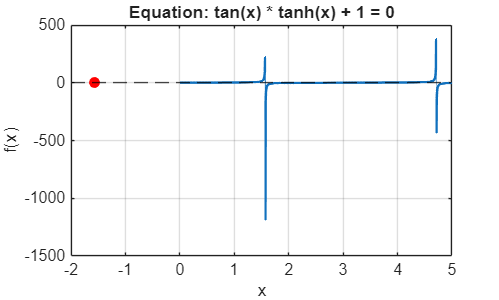

x_vals = linspace(0, 5, 1000);
plot(x_vals, f(x_vals), 'LineWidth', 1.5);
hold on;
yline(0, '--k');
plot(xnew, 0, 'ro', 'MarkerFaceColor', 'r');
xlabel('x'); ylabel('f(x)');
title('Equation: tan(x) * tanh(x) + 1 = 0');
grid on;